% Define units
meter = 1;
millimeter = 10^(-3) * meter;
nanometer = 10^(-9) * meter;

%%%QUESTION:Why does the new propagation propagate_fresnel_transfer_2d only need to return an amplitude, 
% rather than additionally including new coordinates like previous propagation schemes?

%%%ANSWER:

f = -100 * millimeter; % Focal length in meters
lambda = 532 * nanometer; % Wavelength in meters

N = 512; % Size of the grid

% Generate 2D coordinates
coordinates = generate_2d_coordinates(N, 2 * millimeter);

% Phase randomization parameters
a = 0.0009;
ds = sqrt(sum(coordinates.^2, 3)) / a;

% Spectrum calculation
spect = (ds + 1).^-((5/3) * (ds / a).^2 .* (1 + exp(-ds / a)).^-1);

% Generate random phase and apply the spectrum
phi_random = fftshift(real(fft2(fftshift(exp(2i * pi * rand(N, N)) .* randn(N, N) .* spect))));

% Create a pill-shaped beam and apply the random phase
amplitude = exp(1.0i * phi_random) .* (coordinates(:,:,1).^2 + 0.0001 * millimeter) ...
    .* gaussian(coordinates(:,:,2), 0.3 * millimeter) ...
    .* gaussian(coordinates(:,:,1), 0.3 * millimeter);

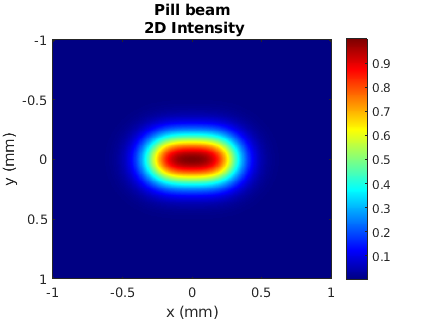

plot_2d_intensity(coordinates, amplitude, "Pill beam")

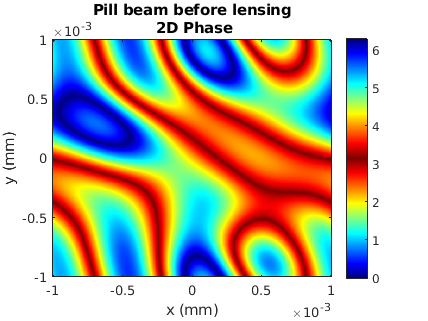

plot_2d_phase(coordinates, amplitude,"Pill beam before lensing")

% Lens the beam
amplitude = amplitude .* lens(coordinates, f, lambda);

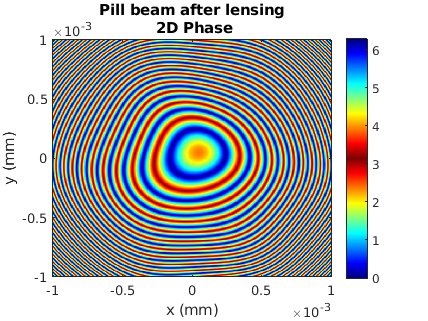

plot_2d_phase(coordinates, amplitude,"Pill beam after lensing")

%%%%TASK: Given the beam provided amplitude after a 10cm lens,
% compute the "amplitude" field at 20 points along the propagation out to 27cm.
% Start by propagating into the Fresnel region before the focus.
% Hint: always propagate from the initial conditions I provide "amplitude", 
% that way error does not build as it would successive propagations.

Invalid expression. Check for missing or extra characters.

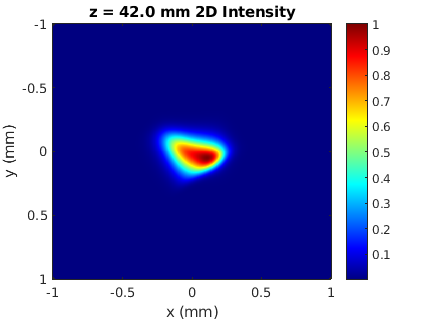

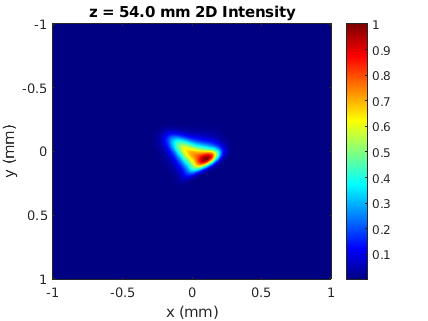

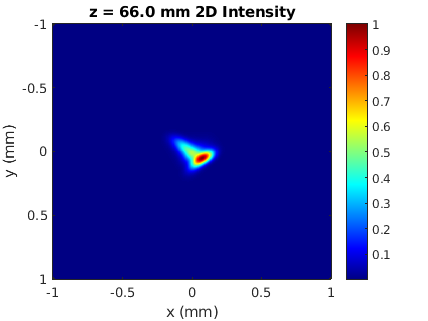

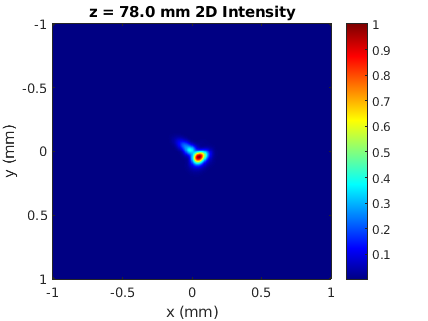

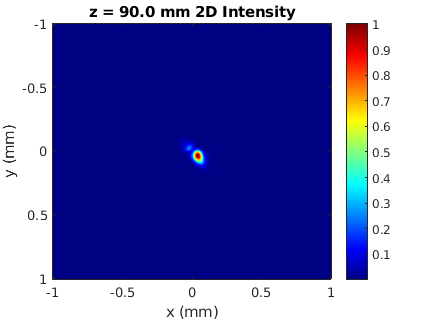

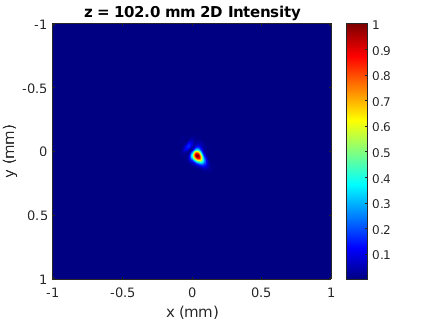

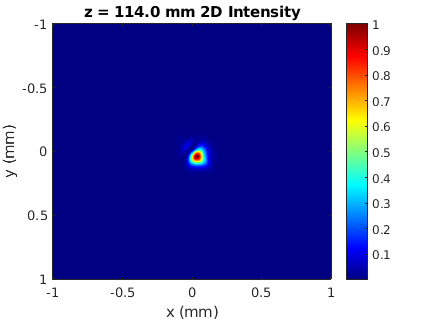

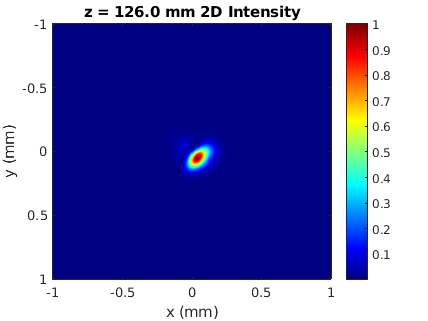

% Arrays to store the measured beam widths over propagation
wxs = []; % Initialize empty array for wxs
wys = []; % Initialize empty array for wys
zs = [];  % Initialize empty array for zs

% Propagation parameters
initial_distance = 30 * millimeter; % Initial distance
step_distance = 12 * millimeter; % Step distance

% Loop from 1 to 20
for i = 1:20
    % Calculate the propagation distance
    propagation_distance = %Propagate to 20 distances, up to 27cm away
    
    % Propagate the amplitude using the Fresnel transfer function
    amplitude_prop = %Propagation of the z=0 field to the i'th distance
    
    % Get beam parameters
    [wx, wy, cx, cy] = %Calculate the beam widths and centroids
    
    % Store the results
    zs = [zs, propagation_distance]; % Append to zs
    wxs = [wxs, wx]; % Append to wxs
    wys = [wys, wy]; % Append to wys
    
    % Plot 2D intensity
    plot_2d_intensity(coordinates, amplitude_prop, sprintf('z = %.1f mm', zs(end) / millimeter));
    pause(0.1); % Pause to allow the plot to update
    figure
end

%%%Question: Show your calculation for where the Fresnel approximation valid 
% region begins (Hint: far enough that the Fresnel approximation holds reasonably, but under 10cm).

%Answer:


%%%TASK: For each of those 20 propagation planes above, calculate the X and Y widths using 
% "beam_parameters_2d", store them into arrays "wxs", "wys". Also store in the provided array 
% "zs" the propagation distance associated with each pair of widths.

%%%Task: Fit the M2model to the X and Y widths. Hint: As a test set phi_random = 0 and 
% make sure your M2 parameter is 1.0 in the short axis (this indicates that the Gaussian beam has 
% M2 1.0). Important: beam parameters generated by our code are 1 widths, 
% but the formulation of the  M2 model given is for 2, multiply the provided widths by 2 before 
% making the fit.

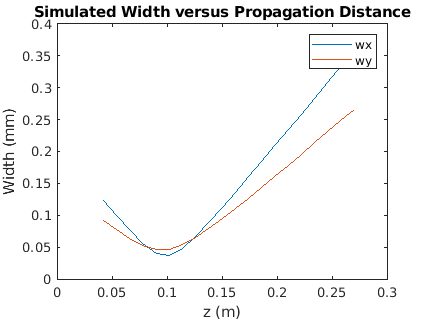

% Convert wxs and wys to millimeters
wxs_mm = wxs / millimeter; % Assuming wxs is defined and millimeter is a conversion factor
wys_mm = wys / millimeter;  % Assuming wys is defined

% Plotting
figure; % Create a new figure
plot(zs, wxs_mm, 'DisplayName', 'wx'); % Plot wxs
hold on; % Hold the current plot
plot(zs, wys_mm, 'DisplayName', 'wy'); % Plot wys
hold off; % Release the hold

% Labeling the axes and adding title
xlabel('z (m)');
ylabel('Width (mm)');
title('Simulated Width versus Propagation Distance');
legend; % Show the legend

% Saving the figure
saveas(gcf, 'width_versus_z.png', 'png'); % Save the current figure


% Show the plot
shg; % Show the current figure window

% Ensure W is defined properly, and that lambda is already defined.
% Initial guess for parameters [W0, M2, z0]
p0 = [%Initial guess should be near a Gaussian beam through a 10cm lens];

% Parameters for fitting
wxs_array = %Widths to fit, should be 2sigma widths

% Define the objective function for fminsearch (sum of squared differences)
objective_function = @(p) sum((W(zs, p(1), p(2), p(3), lambda) - wxs_array).^2);

% Run fminsearch for the curve fitting
[cfx, fval, exitflag, output] = fminsearch(objective_function, p0);
cfx

% Ensure W is defined properly, and that lambda is already defined.
% Initial guess for parameters [W0, M2, z0]
p0 = [%Initial guess should be roughly a Gaussian beam through a 10cm lens];

% Parameters for fitting
wys_array =%Widths to fit, should be 2sigma widths

% Define the objective function for fminsearch (sum of squared differences)
objective_function = @(p) sum((W(zs, p(1), p(2), p(3), lambda) - wys_array).^2);

% Run fminsearch for the curve fitting
[cfy, fval, exitflag, output] = fminsearch(objective_function, p0);
cfy

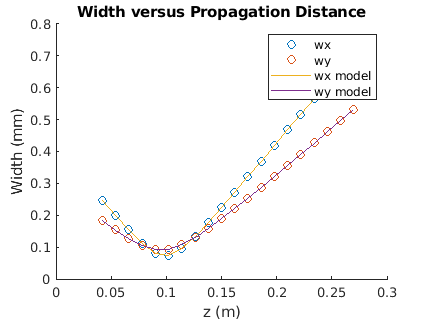

% Create a new figure
figure;

% Scatter plots for wxs and wys
scatter(zs, 2 * wxs / millimeter, 'DisplayName', 'wx'); % Scatter plot for wxs
hold on; % Hold the current plot
scatter(zs, 2 * wys / millimeter, 'DisplayName', 'wy'); % Scatter plot for wys

% Plot the model fits
plot(zs, W(zs, cfx(1), cfx(2), cfx(3), lambda) / millimeter, 'DisplayName', 'wx model'); % wx model
plot(zs, W(zs, cfy(1), cfy(2), cfy(3), lambda) / millimeter, 'DisplayName', 'wy model'); % wy model
hold off; % Release the hold

% Labeling the axes and adding title
xlabel('z (m)');
ylabel('Width (mm)');
title('Width versus Propagation Distance');
legend; % Show the legend

% Saving the figure
saveas(gcf, 'width_versus_z_model_fit.png', 'png'); % Save the current figure


% Show the plot
shg; % Show the current figure window

%%%Question: do the focal planes have the same coordinate (z0x,z0y)? 
% How do  the focal plane z0x,z0y coordinates compare to the lens focal length?

%%%Answer:
